# MATLAB for Business Analytics: Forecasting, Optimization, and AI Agents

You will not need to write algorithms from scratch today.

Every technique here is a single MATLAB function or app - your job is to interpret what it tells you about the business, the same way you would read output from Excel, Power BI, or SPSS.

We follow one fictional retailer, **Brighten Up Mart**, through three connected decisions that any retail, logistics, or supply-chain manager faces every month.

- **Part 1 - Machine Learning for Forecasting:** how much will customers buy next quarter?

- **Part 2 - Transportation Optimization:** given that demand, what is the cheapest way to ship inventory to stores?

- **Part 3 - AI Agentics for Data Analytics and Dashboard Intelligence:** how do we turn all of this into a dashboard - and an assistant - that busy executives can actually use

## The Business Scenario

Brighten Up Mart is a Thai retail chain with three regional distribution centers and five stores.

Every month, the management team has to answer three questions: *How much will we sell?*, *How do we distribute stock at the lowest cost?*, and *How do we get answers fast, without waiting for an analyst?*

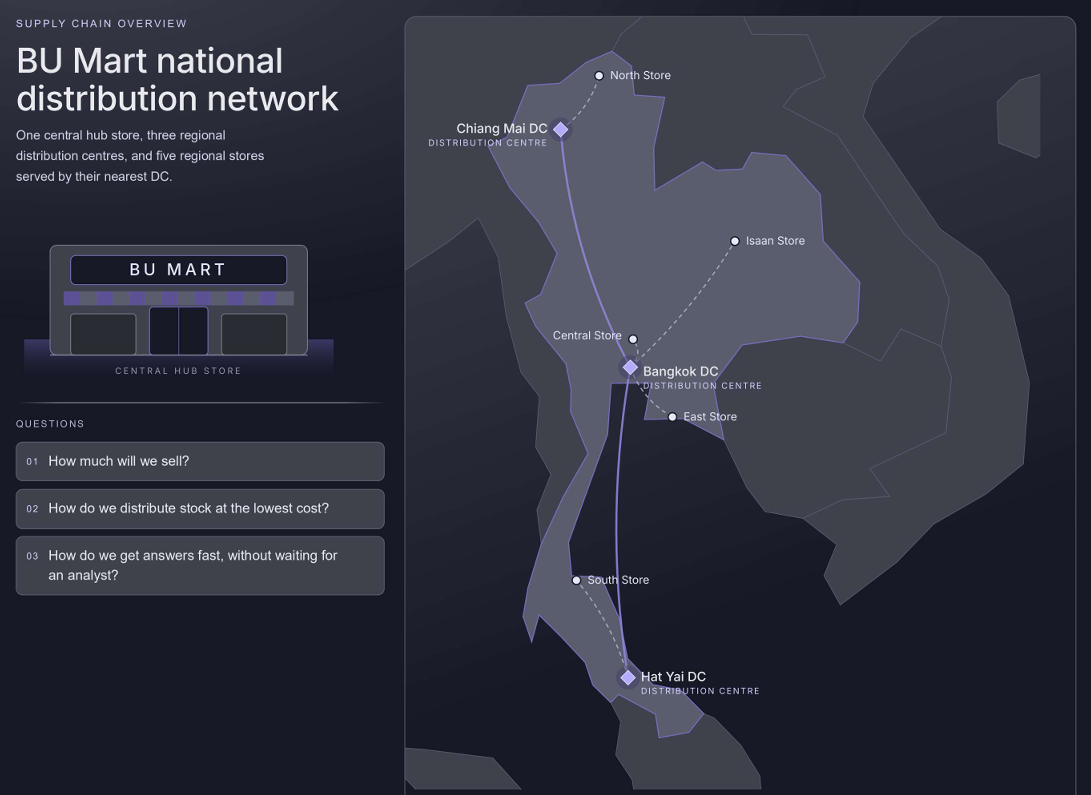

We start by loading four years of monthly sales history, together with the marketing budget spent each month - a common early-warning signal for demand.

### Import Data using Live Task

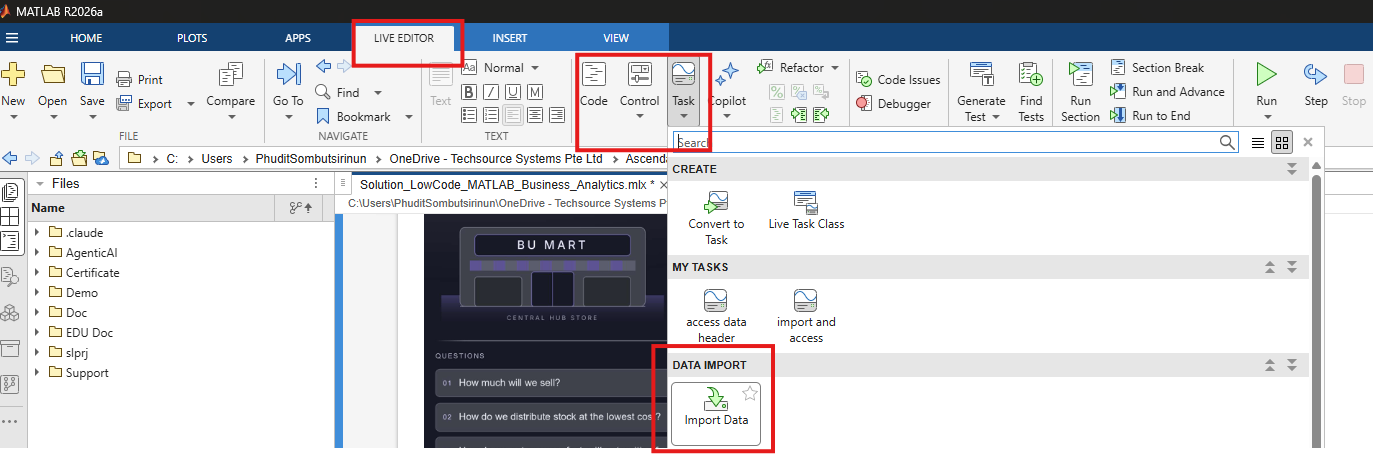

% Import data from text file
BUS = readtimetable(".\data\BrightenUpMartSales.csv", "RowTimes", ...
    "Month");

% Display results
BUS

BUS = 48×2 timetable
       Month       Sales    MarketingSpend
    ___________    _____    ______________

    01-Jan-2022     560           31      
    01-Feb-2022     590           47      
    01-Mar-2022     543           36      
    01-Apr-2022     807          117      
    01-May-2022     699           52      
    01-Jun-2022     722           41      
    01-Jul-2022     721           40      
    01-Aug-2022     615           28      
    01-Sep-2022     601           38      
    01-Oct-2022     588           40      
    01-Nov-2022     791          122      
    01-Dec-2022     800          125      
    01-Jan-2023     579           37      
    

Want summary of the data?

summary(BUS)


BUS: 48×2 timetable

Row Times:

    Month: datetime

Variables:

    Sales: double
    MarketingSpend: double

Statistics for applicable variables and row times:

                      NumMissing          Min              Median               Max               Mean                Std      

    Month                 0           01-Jan-2022        16-Dec-2023        01-Dec-2025        16-Dec-2023        10230:30:19  
    Sales                 0                   543                723                933           723.3958           102.1165  
    MarketingSpend        0                    21                 41                129            58.8958            35.3422  



## A First Look at the Data

Before modeling anything, always plot the raw series.

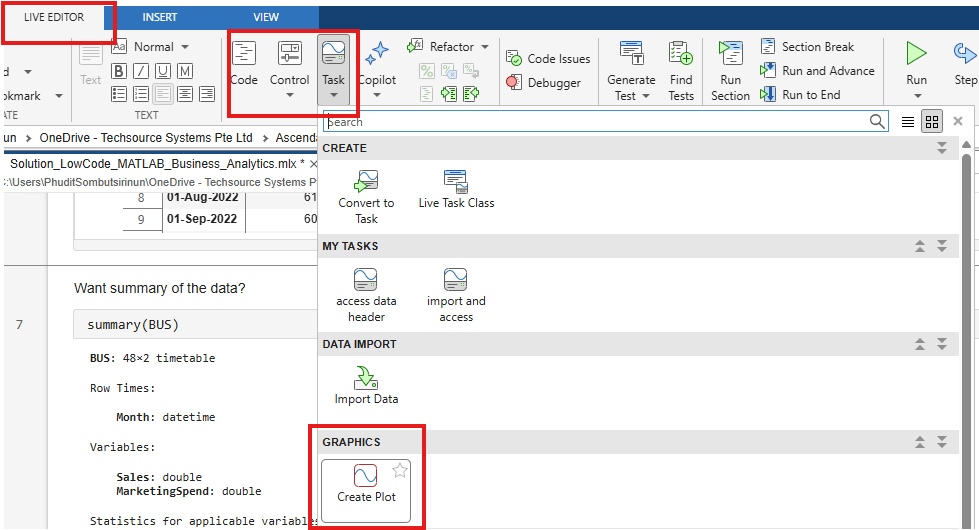

### Try to find some correlation between data

Sales against `MarketingSpend`: does spend actually move sales, that is, is it worth using as a predictor? 

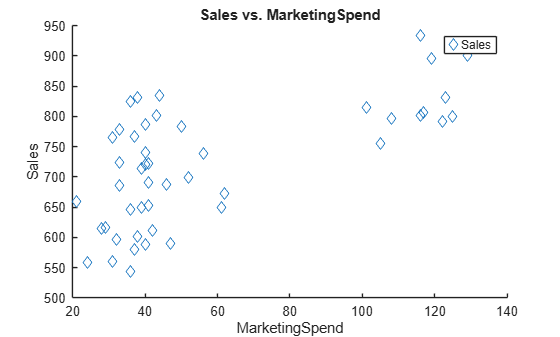

% Create scatter of BUS.MarketingSpend and BUS.Sales
sm = scatter(BUS,"MarketingSpend","Sales","Marker","diamond","DisplayName","Sales");

% Add xlabel, ylabel, title, and legend
xlabel("MarketingSpend")
ylabel("Sales")
title("Sales vs. MarketingSpend")
legend

### Plot unit sales in time

Sales against `Month`: is there a trend, and does the same shape repeat every 12 months?

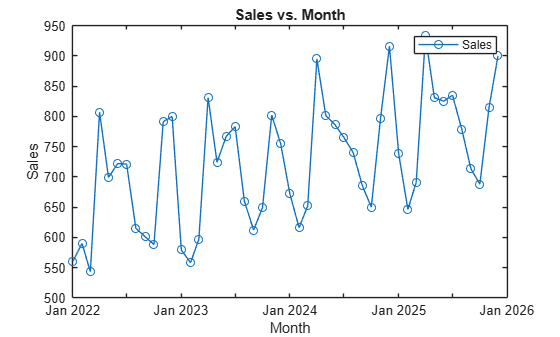

% Create plot of BUS.Month and BUS.Sales
s = plot(BUS,"Month","Sales","Marker","o","DisplayName","Sales");

% Add xlabel, ylabel, title, and legend
xlabel("Month")
ylabel("Sales")
title("Sales vs. Month")
legend

## Part 1: Machine Learning for Forecasting

### How the Regression Model Actually Learns

- **Supervised learning.** You give the algorithm examples where the answer is already known - here, 36 months in which both the four features and the actual `Sales` are recorded. Learning means finding a function `f` such that `f(features)` comes as close as possible to the observed sales, and then applying that same `f` to a month whose answer you do not have.

- **What fitting means.** A linear model is just a weighted sum: `Sales = b0 + b1*feature1 + b2*feature2 + ...`. Fitting picks the five `b` values that make the total squared error across all training rows as small as possible. Nothing more mysterious than that - the app simply tries many model families and reports which one does it best.


### Turning History into Learning Examples

A regression has no sense of time; it sees only the columns you hand it. Each of the four features smuggles in a different piece of business knowledge:

- `MonthOfYear` carries calendar effects - Songkran, year-end, school terms.

- `LastMonth` carries momentum: whatever is happening now tends to continue.

- `SameMonthLastYear` carries seasonality, the annual shape you saw in the Step 0 plot.

- `MarketingSpend` carries the one driver management can actually control, which is what makes the model useful for planning rather than merely watching

% Import data from text file
BUS_Features = readtable(".\data\BrightenUpMartSales_Features.csv");

% Display results
BUS_Features

BUS_Features = 36×5 table
    MonthOfYear    LastMonth    SameMonthLastYear    MarketingSpend    Sales
    ___________    _________    _________________    ______________    _____

         1            800              560                 37           579 
         2            579              590                 24           558 
         3            558              543                 32           597 
         4            597              807                123           831 
         5            831              699                 33           724 
         6            724              722                 37           767 
         7            767              721                 50           783 
         8            783              615                 21           660 
         9            660        

### Train/Test Split

The first 3 years data is used to **train** the model. The latest year is held back as a** test** data

BUS_train = BUS_Features(1:24,:)

BUS_train = 24×5 table
    MonthOfYear    LastMonth    SameMonthLastYear    MarketingSpend    Sales
    ___________    _________    _________________    ______________    _____

         1            800              560                 37           579 
         2            579              590                 24           558 
         3            558              543                 32           597 
         4            597              807                123           831 
         5            831              699                 33           724 
         6            724              722                 37           767 
         7            767              721                 50           783 
         8            783              615                 21           660 
         9            660           

BUS_test = BUS_Features(25:end,:)

BUS_test = 12×5 table
    MonthOfYear    LastMonth    SameMonthLastYear    MarketingSpend    Sales
    ___________    _________    _________________    ______________    _____

         1            916              672                 56           738 
         2            738              616                 36           646 
         3            646              652                 41           691 
         4            691              895                116           933 
         5            933              801                 38           831 
         6            831              786                 36           825 
         7            825              765                 44           835 
         8            835              740                 33           779 
         9            779            

### Training the Model by Regression Learner App

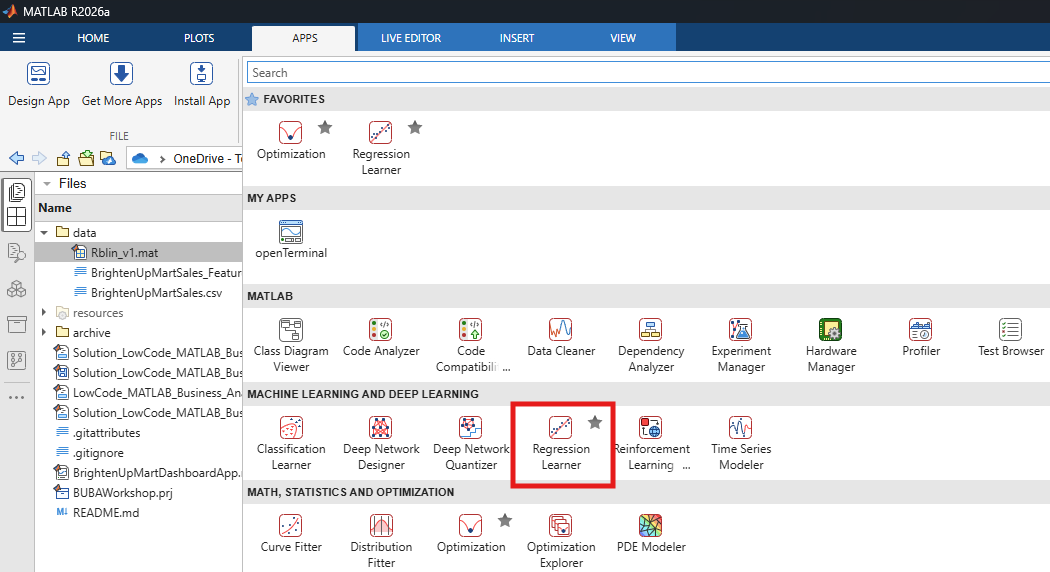

% or open it in by type "regressionLearner" in code

% regressionLearner
load data\RbLin.mat

### Explain Model Predictions

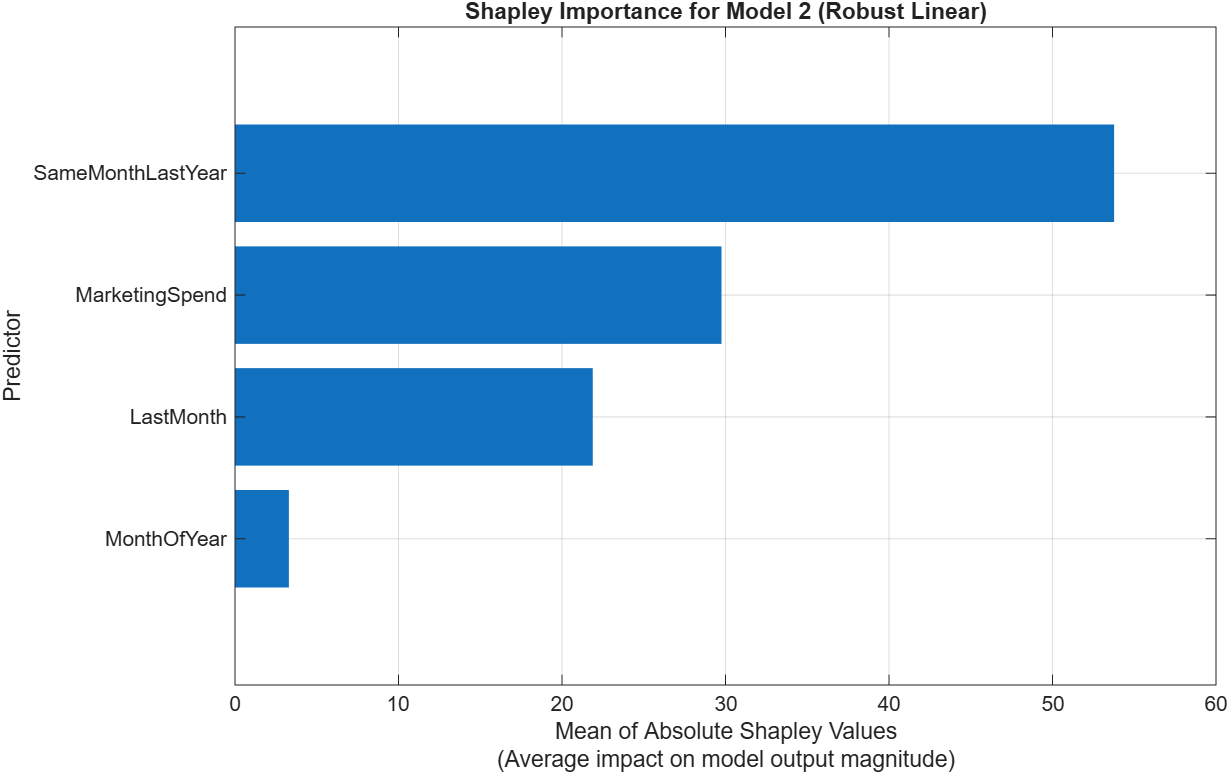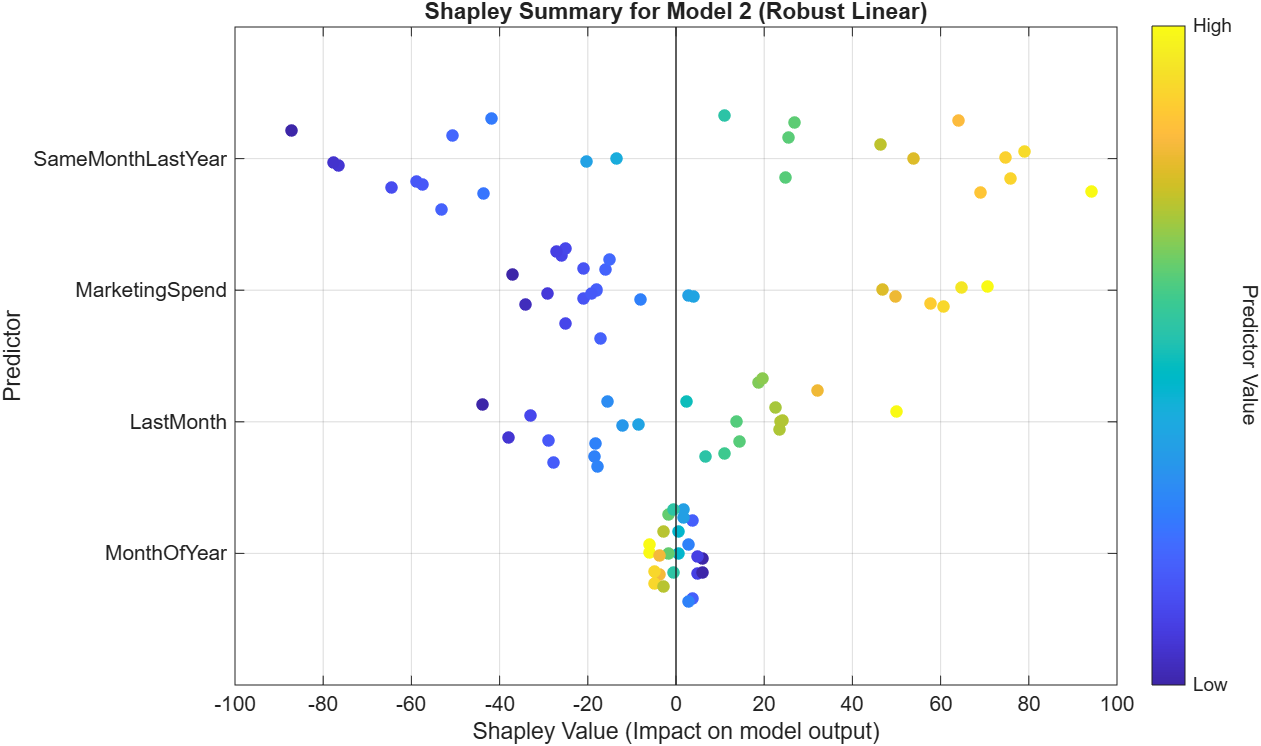

### Forecast the 3rd year sales

prepare the input table

input = BUS_test(:,1:4)

input = 12×4 table
    MonthOfYear    LastMonth    SameMonthLastYear    MarketingSpend
    ___________    _________    _________________    ______________

         1            916              672                 56      
         2            738              616                 36      
         3            646              652                 41      
         4            691              895                116      
         5            933              801                 38      
         6            831              786                 36      
         7            825              765                 44      
         8            835              740                 33      
         9            779              685                 39      
        10            713              650                 46      
        11            688   

prediction

forecast3rdYrSales = RbLin.predictFcn(input);

compare the result

m = BUS.Month(37:end); % date array for plotting

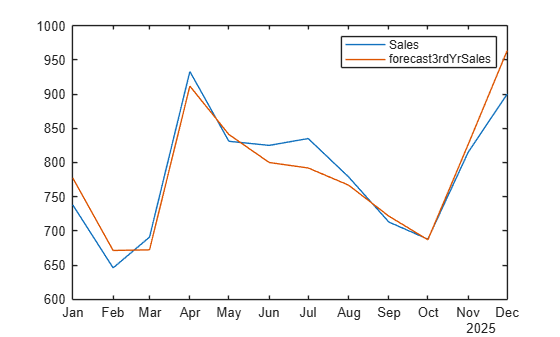

figure
% Create plot of selected data
plot(m,BUS_test.Sales,"DisplayName","Sales");

hold on
% Create plot of m and forecast3rdYrSales
plot(m,forecast3rdYrSales,"DisplayName","forecast3rdYrSales");
hold off

legend

### Roll the model forward (recursive forecasting)

The model predicts **one** month. A multi-month forecast is therefore recursive: predict month h, then feed that prediction straight back in as the next month's `LastMonth`, while `SameMonthLastYear` is read from the history 12 months earlier.

As shown earlier, the input needed for forecasting are

- Month of Year ( i.e. 1 for Jan, 2 for Feb)

- Last Month Sales

- Same Month Last Year Sales

- Marketing Spend

Let's go step by step. Starting with forecast the upcoming month

#### Step-by-Step Forecasting

create needed input one by one

assign next month value

nextMonth = 1

nextMonth = 1

access last month sales

lastMonthSales = BUS.Sales(end)

lastMonthSales = 900

access same month last year sales

sameMonthLastYearSales = BUS.Sales(end-12+1)

sameMonthLastYearSales = 738

assign marketing spend

marketSpend = 42

marketSpend = 42

put all of them in a table

input = table(nextMonth,lastMonthSales,sameMonthLastYearSales,marketSpend, ...
    'VariableNames', {'MonthOfYear','LastMonth','SameMonthLastYear','MarketingSpend'})

input = 1×4 table
    MonthOfYear    LastMonth    SameMonthLastYear    MarketingSpend
    ___________    _________    _________________    ______________

         1            900              738                 42      

	Get insights using Copilot


predict the next month sales

nextMonthSales = RbLin.predictFcn(input)

nextMonthSales = 800.4737

Now, do the same for next month (2), but the last month data is` nextMonthSales`

nextMonth = 2;
sameMonthLastYearSales = BUS.Sales(end-12+2)

sameMonthLastYearSales = 646

marketSpend = 38;
lastMonthSales = nextMonthSales;
input = table(nextMonth,lastMonthSales,sameMonthLastYearSales,marketSpend,...
    'VariableNames', {'MonthOfYear','LastMonth','SameMonthLastYear','MarketingSpend'})

input = 1×4 table
    MonthOfYear    LastMonth    SameMonthLastYear    MarketingSpend
    ___________    _________    _________________    ______________

         2          800.47             646                 38      

	Get insights using Copilot


nextMonthSales = RbLin.predictFcn(input)

nextMonthSales = 709.7446

Repeat the process until the desired duration is met. Easy? What if we want 50-years data?

#### Loop Function for Forecasting

targetm = 6; % forecast the next 6 months
focusmkt = 4; % boost marketing spend on April
[futureDates, plannedSpend, forecastSales] = createForecast(BUS, targetm, focusmkt, 'RbLin');
forecastTbl = table(futureDates, round(forecastSales), plannedSpend, 'VariableNames', {'Month','ForecastSales','PlannedMarketingSpend'})

forecastTbl = 6×3 table
       Month       ForecastSales    PlannedMarketingSpend
    ___________    _____________    _____________________

    01-Jan-2026         800                   42         
    01-Feb-2026         710                   38         
    01-Mar-2026         716                   42         
    01-Apr-2026         947                  121         
    01-May-2026         871                   45         
    01-Jun-2026         839                   39         

	Get insights using Copilot


### Plotting the Forecast

The forecast picks up right where history ends, and clearly shows the expected April demand spike from the planned promotion - exactly the kind of signal that feeds into Part 2.

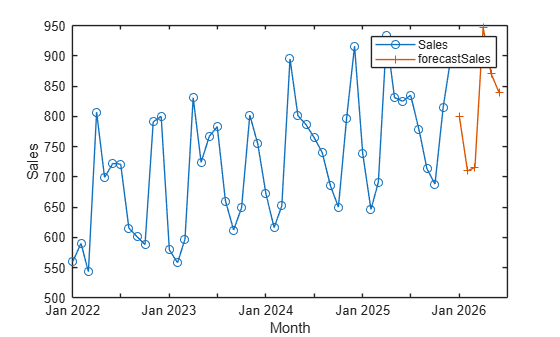

figure
% Create plot of BUS.Month and BUS.Sales
plot(BUS,"Month","Sales","Marker","o","DisplayName","Sales");

hold on
% Create plot of futureDates and forecastSales
plot(futureDates,forecastSales,"Marker","+","DisplayName","forecastSales");
hold off

legend

## Part 2: Transportation Optimization

Forecasting tells us Brighten Up Mart needs to move about 947 units in April.

The next business question is purely operational: given three distribution centers with limited capacity and five stores that must each receive their share, which shipping routes should we use to meet every store's demand at the lowest possible total shipping cost?

This is the classic *transportation problem*, and it is a perfect example of business **optimization**: instead of trying options by hand in a spreadsheet, we let MATLAB search every feasible shipping plan and return the mathematically cheapest one..


### Setting Up the Distribution Network

The network scenario comes from `data\TransportOpt.xlsx`, one sheet each: **Shipping Cost** (THB per unit on each of the 3 by 5 centre-to-store routes), **Supply Share** (how capacity divides across the three distribution centres), and **Demand Share** (how demand divides across the five stores).

Each distribution center (DC) has a maximum monthly capacity, each store has a demand it must receive in full, and shipping a unit costs a different amount on every route depending on distance.

#### Import Shipping cost

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 6);

% Specify sheet and range
opts.Sheet = "Shipping Cost";
opts.DataRange = "B3:G5";

% Specify column names and types
opts.VariableNames = ["DistributionCenter", "NorthStore", "CentralStore", "EastStore", ...
    "SouthStore", "IsaanStore"];
opts.VariableTypes = ["string", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, "DistributionCenter", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "DistributionCenter", "EmptyFieldRule", "auto");

% Import the data
shipCostT = readtable(".\data\TransportOpt.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
shipCostT

shipCostT = 3×6 table
    DistributionCenter    NorthStore    CentralStore    EastStore    SouthStore    IsaanStore
    __________________    __________    ____________    _________    __________    __________

     "Bangkok DC"            2000            600           900          2500          1500   
     "Chiang Mai DC"          700           2000          2300          3700          1800   
     "Hat Yai DC"            3700           2500          2600           700          2800   

	Get insights using Copilot


convert table to array

shipCost = table2array(shipCostT(:,2:end))

shipCost =         2000         600         900        2500        1500
         700        2000        2300        3700        1800
        3700        2500        2600         700        2800


#### Import Supply Share

% Set up the Import Options and import the data
opts2 = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts2.Sheet = "Supply Share";
opts2.DataRange = "B3:C5";

% Specify column names and types
opts2.VariableNames = ["DistributionCenter", "PctSupplyShare"];
opts2.VariableTypes = ["string", "double"];

% Specify variable properties
opts2 = setvaropts(opts2, "DistributionCenter", "WhitespaceRule", "preserve");
opts2 = setvaropts(opts2, "DistributionCenter", "EmptyFieldRule", "auto");

% Import the data
SupplyShare = readtable(".\data\TransportOpt.xlsx", opts2, "UseExcel", false);

% Clear temporary variables
clear opts2

% Display results
SupplyShare

SupplyShare = 3×2 table
    DistributionCenter    PctSupplyShare
    __________________    ______________

     "Bangkok DC"              0.47     
     "Chiang Mai DC"           0.29     
     "Hat Yai DC"              0.24     

	Get insights using Copilot


assign DC names and  DC share

dcNames = SupplyShare.DistributionCenter

dcNames = 3×1 string array
    "Bangkok DC"
    "Chiang Mai DC"
    "Hat Yai DC"


dcShare = SupplyShare.PctSupplyShare

dcShare =     0.4700
    0.2900
    0.2400


#### Import Demand Share

% Set up the Import Options and import the data
opts3 = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts3.Sheet = "Demand Share";
opts3.DataRange = "B3:C7";

% Specify column names and types
opts3.VariableNames = ["Stores", "PctDemandShare"];
opts3.VariableTypes = ["string", "double"];

% Specify variable properties
opts3 = setvaropts(opts3, "Stores", "WhitespaceRule", "preserve");
opts3 = setvaropts(opts3, "Stores", "EmptyFieldRule", "auto");

% Import the data
demandShare = readtable(".\data\TransportOpt.xlsx", opts3, "UseExcel", false);

% Clear temporary variables
clear opts3

% Display results
demandShare

demandShare = 5×2 table
        Stores         PctDemandShare
    _______________    ______________

    "North Store"          0.217     
    "Central Store"        0.265     
    "East Store"           0.181     
    "South Store"          0.169     
    "Isaan Store"          0.168     

	Get insights using Copilot


assign store names and store share

storeNames = demandShare.Stores

storeNames = 5×1 string array
    "North Store"
    "Central Store"
    "East Store"
    "South Store"
    "Isaan Store"


storeShare = demandShare.PctDemandShare

storeShare =     0.2170
    0.2650
    0.1810
    0.1690
    0.1680


**Total Demand and Supply** assign total demand from forecast data on the focus marketing month, then calculate total supply from total demand; a three percent buffer so the plan is not knife-edge

totalDemand = round(forecastTbl.ForecastSales(focusmkt))

totalDemand = 947

totalSupply = ceil(totalDemand*1.03)

totalSupply = 976

**Store demand:** `demand = round(totalDemand*storeShare)`. Rounding five shares rarely sums back to the total, so the remainder is pushed onto the last store. The store demands must sum exactly to `totalDemand`, or the equality constraint in the **Optimization** step cannot be satisfied.

demand = round(totalDemand*storeShare);
demand(end) = demand(end) + (totalDemand - sum(demand)); % make the summation of store demand equal to total demand
demand

demand =    205
   251
   171
   160
   160


**DC supply:** `totalSupply `split by `dcShare` with the remainder added to the first centre.

supply = round(totalSupply*dcShare);
supply(1) = supply(1) + (totalSupply - sum(supply));
supply

supply =    459
   283
   234


### Solving for the Least-Cost Shipping Plan by Optimize Live Task

The **Optimize** Live Task asks for the decision in business language, not for an algorithm. Four entries specify it completely:

- **Decision variable:** `shipUnit`, a 3 by 5 matrix holding how many units travel on each route, with a lower bound of 0 because you cannot ship negative stock.

- **Objective, minimise:** `sum(sum(shipCost.*shipUnit))`, the total shipping bill in THB.

- **Capacity constraint:** `sum(shipUnit,2) <= supply`. Summing each row across stores means no distribution centre ships more than it holds.

- **Service constraint:** `sum(shipUnit,1)' == demand`. Summing each column across centres means every store receives its full demand. Equality, not `<=`, because partial delivery is not an option her

% Create optimization variables
shipUnit2 = optimvar("shipUnit",3,5,"LowerBound",0);

% Set initial starting point for the solver
initialPoint.shipUnit = zeros(size(shipUnit2));

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = sum(sum(shipCost.*shipUnit2));

% Define problem constraints
problem.Constraints.constraint1 = sum(shipUnit2,2) <= supply;
problem.Constraints.constraint2 = sum(shipUnit2,1)' == demand;

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       shipUnit

	minimize :
       2000*shipUnit(1, 1) + 700*shipUnit(2, 1) + 3700*shipUnit(3, 1) + 600*shipUnit(1, 2) + 2000*shipUnit(2, 2) + 2500*shipUnit(3, 2) + 900*shipUnit(1, 3) + 2300*shipUnit(2, 3) + 2600*shipUnit(3, 3) + 2500*shipUnit(1, 4) + 3700*shipUnit(2, 4) + 700*shipUnit(3, 4) + 1500*shipUnit(1, 5) + 1800*shipUnit(2, 5) + 2800*shipUnit(3, 5)


	subject to constraint1:
       shipUnit(1, 1) + shipUnit(1, 2) + shipUnit(1, 3) + shipUnit(1, 4) + shipUnit(1, 5) <= 459
       shipUnit(2, 1) + shipUnit(2, 2) + shipUnit(2, 3) + shipUnit(2, 4) + shipUnit(2, 5) <= 283
       shipUnit(3, 1) + shipUnit(3, 2) + shipUnit(3, 3) + shipUnit(3, 4) + shipUnit(3, 5) <= 234

	subject to constraint2:
       shipUnit(1, 1) + shipUnit(2, 1) + shipUnit(3, 1) == 205
       shipUnit(1, 2) + shipUnit(2, 2) + shipUn


% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint);


Solving problem using linprog.

Optimal solution found.




% Display results
solution

solution = struct with fields:
    shipUnit: [3×5 double]


reasonSolverStopped

reasonSolverStopped =     OptimalSolution


objectiveValue

objectiveValue = 881900


% Clear temporary variables
clearvars shipUnit2 initialPoint reasonSolverStopped objectiveValue

string(month(forecastTbl.Month(focusmkt),'name'))

ans = "April"

shipTbl = array2table(round(solution.shipUnit), 'VariableNames', storeNames, 'RowNames', dcNames)

shipTbl = 3×5 table
                     North Store    Central Store    East Store    South Store    Isaan Store
                     ___________    _____________    __________    ___________    ___________

    Bangkok DC             0             251            171              0            37     
    Chiang Mai DC        205               0              0              0            78     
    Hat Yai DC             0               0              0            160            45     

	Get insights using Copilot


totalCost = sum(sum(shipCost .* solution.shipUnit))

totalCost = 881900

### How Much Did Optimization Save?

To show the value of optimization, we compare it against a common real-world habit: allocating stock first-come, first-served, store by store, without considering cost at all.

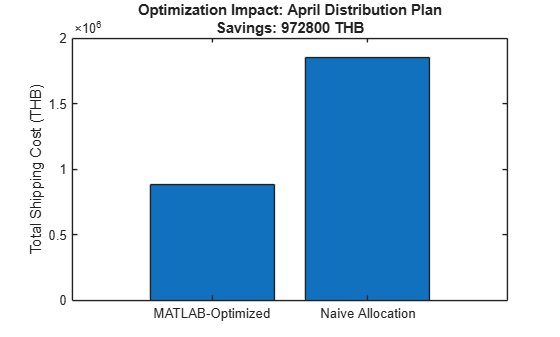

[alloc, naiveCost, savings] = naiveAllocation(supply, demand, shipCost, totalCost, forecastTbl, focusmkt);

Optimization saves BrightMart roughly 1M THB on this single month's shipment simply by choosing routes more intelligently, with no change to demand, supply, or prices.

## Part 3: AI Agentics for Data Analytics and Dashboard Intelligence

A forecast and an optimal shipping plan are only useful if the right people see them in time to act.

The plan is optimal **for the numbers you supplied**. Demand came from a forecast, so the honest follow-up question is how much the plan and the bill change if demand turns out five percent higher. That question is the reason the dashboard exists.

Don't know how to build a complex dashboard from MATLAB Live Script? MATLAB Agentic AI toolkit could give you some hands.

### Agentic AI

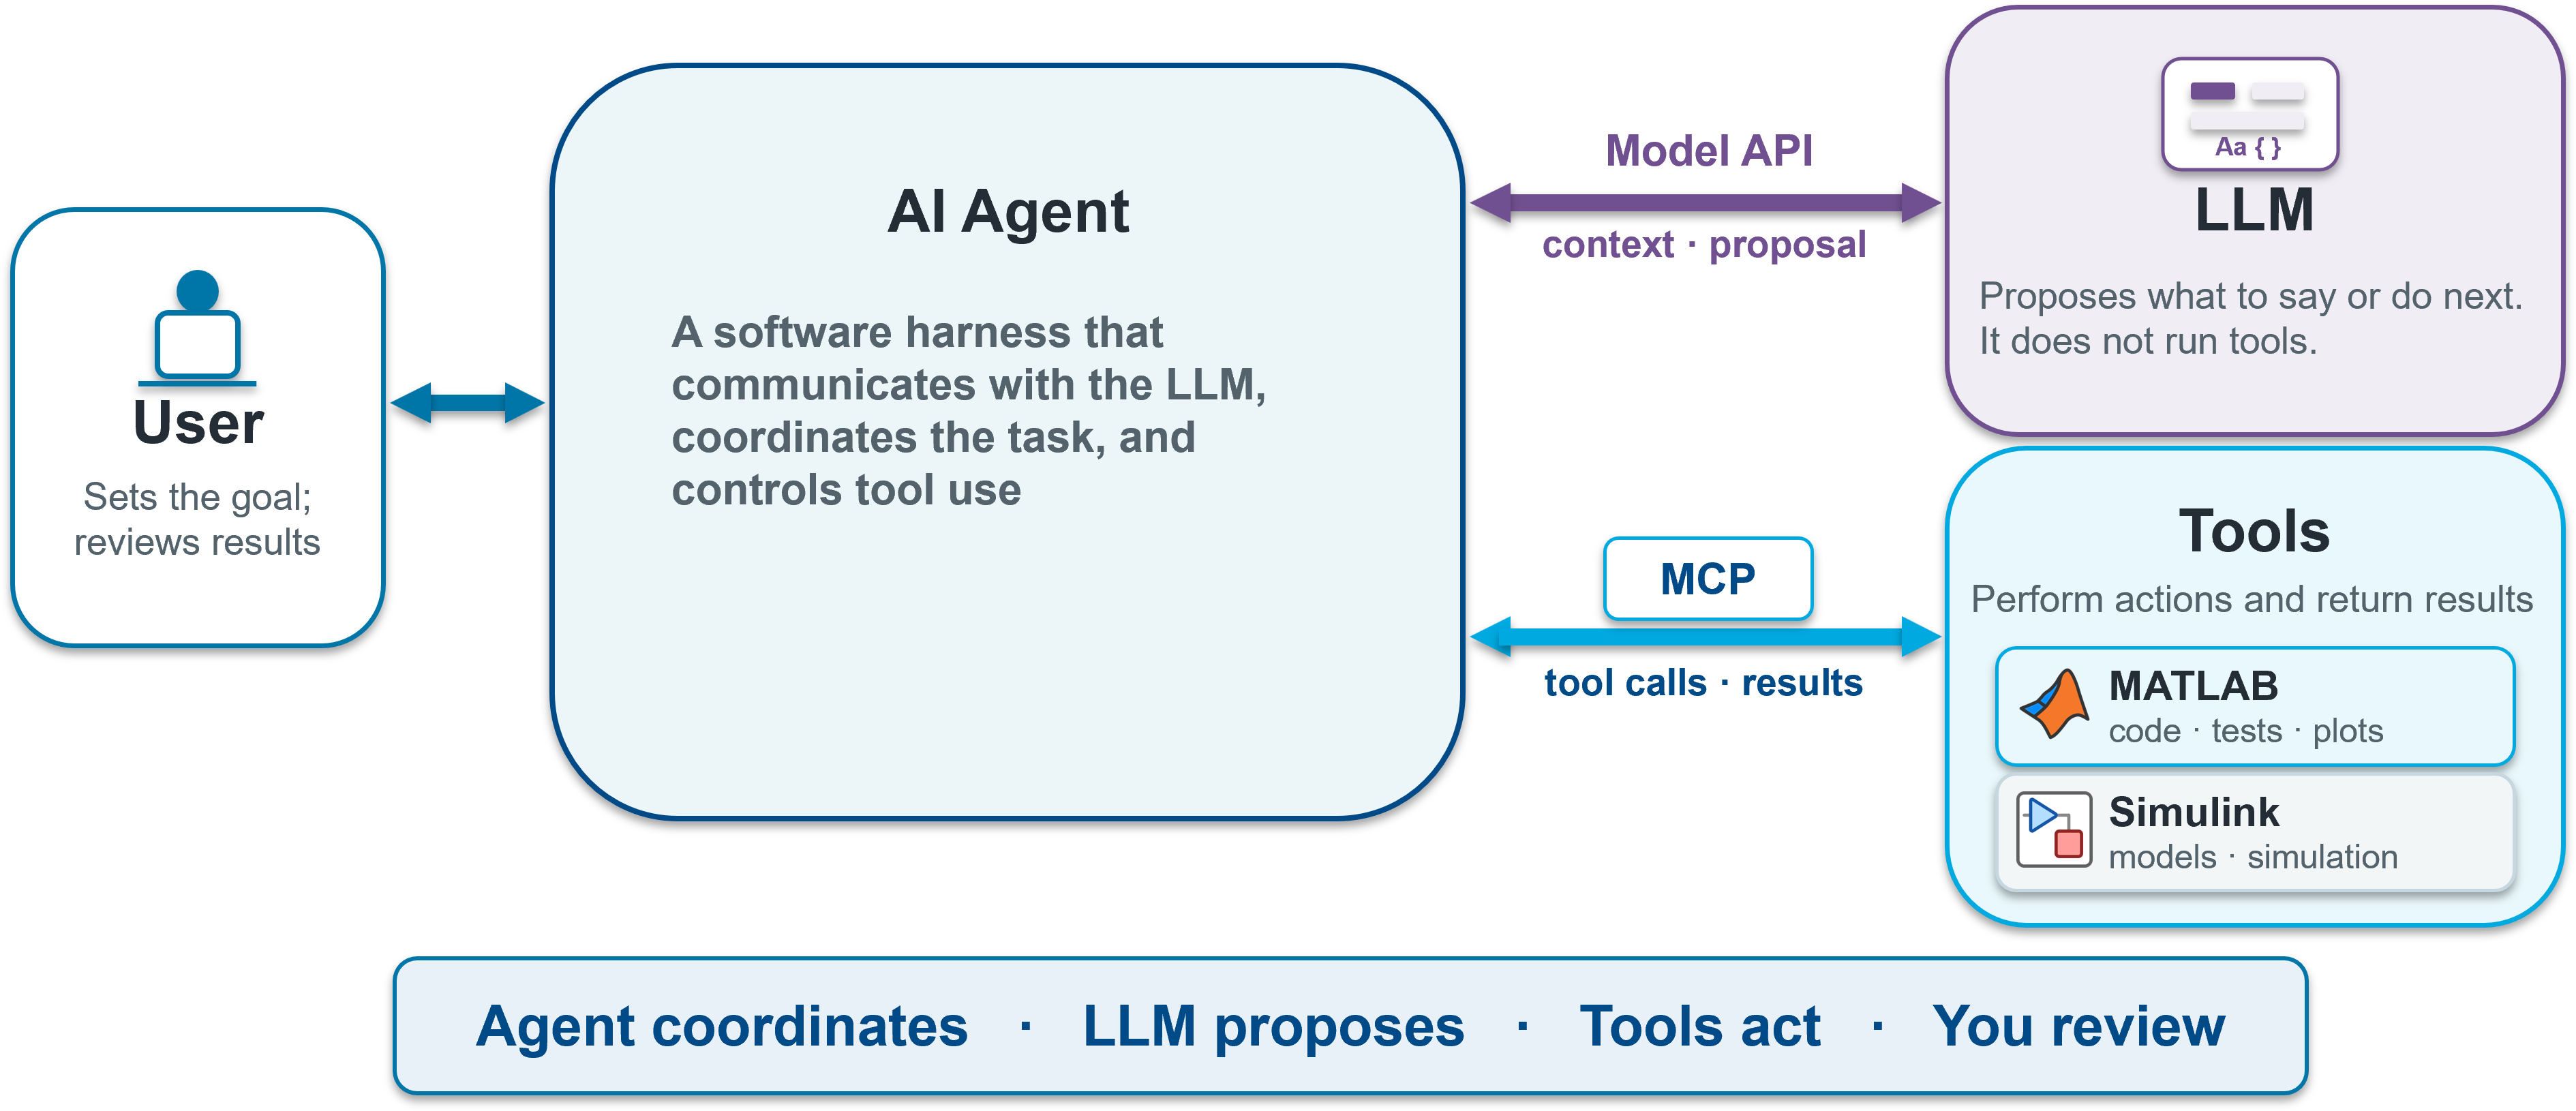

**What an AI agent adds, and what it does not.**

- A language model on its own predicts text. It does not compute, and it has no access to your data. Asking one for next April's sales gets you a fluent number with nothing behind it.

- An **agent** is a language model plus **tools** plus a loop. It reads the question, decides which tool to call - run the forecast, re-solve the shipping plan, look up a row - supplies the arguments, receives the result, and present it according to your prompt. Every number still comes from **MATLAB**. 

% open BrightenUpMartDashboardApp.mlapp
open BrightenUpMartAnalyticsApp.mlapp

## Appendix

If you would like to know how to make the features table from scratch

lag1 = [NaN; BUS.Sales(1:end-1)];
lag12 = [NaN(12,1); BUS.Sales(1:end-12)];
featTbl = table(month(BUS.Month), lag1, lag12, BUS.MarketingSpend, BUS.Sales, ...
    'VariableNames', {'MonthOfYear','LastMonth','SameMonthLastYear','MarketingSpend','Sales'});
featTbl = featTbl(13:end,:);
featTbl

featTbl = 36×5 table
    MonthOfYear    LastMonth    SameMonthLastYear    MarketingSpend    Sales
    ___________    _________    _________________    ______________    _____

         1            800              560                 37           579 
         2            579              590                 24           558 
         3            558              543                 32           597 
         4            597              807                123           831 
         5            831              699                 33           724 
         6            724              722                 37           767 
         7            767              721                 50           783 
         8            783              615                 21           660 
         9            660             

clear lag1 lag12 featTbl 

createForecast function

function [futureDates, plannedSpend, forecastSales] = createForecast(BUS, targetm, focusmkt, model)
%CREATEFORECAST Create future dates, planned marketing spend, and forecasts

    % Resolve model input: struct or name in base workspace
    if ischar(model) || (isstring(model) && isscalar(model))
        modelName = char(model);
        model = evalin('base', modelName);
    end
    if ~isstruct(model) || ~isfield(model,'predictFcn')
        error('createForecast:InvalidModel', 'model must be a struct with a predictFcn field.');
    end

    monthIdx = 1:targetm;                             % create index from defined target m
    futureDates = BUS.Month(end) + calmonths(monthIdx)'; % create futureDates for forecasting
    
    rng(7);                                           % fix random seed
    plannedSpend = poissrnd(median(BUS.MarketingSpend(end-12:end)), [targetm,1]); % randomized planned marketing spend
    plannedSpend(focusmkt) = round(median(BUS.MarketingSpend(end-12:end)) + 2*std(BUS.MarketingSpend(end-12:end))); % assign spike marketing spend
    
    forecastSales = zeros(targetm,1);                 % allocate array for forecastSales
    lag1cur = BUS.Sales(end);                         % last month sales
    for h = monthIdx
        row = table(h, lag1cur, BUS.Sales(end-12+h), plannedSpend(h), ...
            'VariableNames', {'MonthOfYear','LastMonth','SameMonthLastYear','MarketingSpend'});
        forecastSales(h) = model.predictFcn(row);
        lag1cur = forecastSales(h);
    end

end

Naive cost calculation and plot

function [alloc, naiveCost, savings] = naiveAllocation(supply, demand, cost, totalCost, forecastTbl, focusmkt)
%NAIVEALLOCATION Compute a greedy (naive) allocation, cost, savings and plot
%   [alloc, naiveCost, savings] = naiveAllocation(supply, demand, cost, totalCost, forecastTbl, focusmkt)
%   supply : vector of supply by distribution center (nx1)
%   demand : vector of demand by store (1xm or mx1)
%   cost   : nxm cost matrix (same size as allocation)
%   totalCost : optimized total cost (scalar) for comparison
%   forecastTbl, focusmkt : used to label the plot

supply = supply(:);                 % ensure column
demand = demand(:)';                % ensure row
n = numel(supply);
m = numel(demand);
remaining = supply;
alloc = zeros(n,m);

for j = 1:m
    d = demand(j);
    for i = 1:n
        take = min(remaining(i), d);
        alloc(i,j) = take;
        remaining(i) = remaining(i) - take;
        d = d - take;
        if d <= 0
            break
        end
    end
end

naiveCost = sum(sum(cost .* alloc));
savings = naiveCost - totalCost;

% Plot comparison
figure;
bar(categorical({'Naive Allocation','MATLAB-Optimized'}), [naiveCost totalCost]);
ylabel('Total Shipping Cost (THB)');
title({
    sprintf('Optimization Impact: %s Distribution Plan', string(month(forecastTbl.Month(focusmkt),'name'))), ...
    sprintf('Savings: %0.0f THB', savings)
});

end